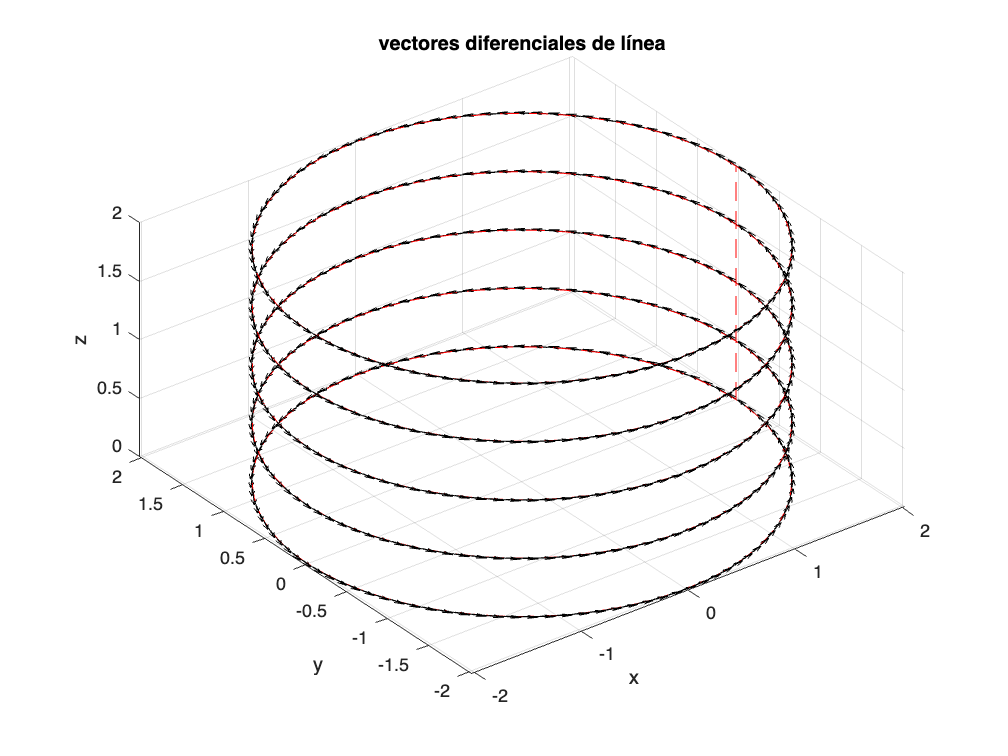

n = 5;   % número de vueltas
r = 2;   % radio
dz = 0.5; % separación entre los puntos
N = 100; % número de puntos

theta = linspace(0, 2*pi, N);
difang = (2*pi)/N;

% inicialización de los arreglos
x_all = [];
y_all = [];
z_all = [];
theta_all = [];

% se construye la posición de cada vuelta
for k = 0:n-1
    x = r * cos(theta);
    y = r * sin(theta);
    z = dz * k * ones(size(theta)); 

    % donde se concatenan todos los valores para cada vuelta
    x_all = [x_all, x];
    y_all = [y_all, y];
    z_all = [z_all, z];
    theta_all = [theta_all, theta];
end


dx = -r * sin(theta_all) * difang;
dy =  r * cos(theta_all) * difang;
dzl = zeros(size(dx)); % indica que el diferencial de linea no tiene componentes en Z


figure
plot3(x_all, y_all, z_all, 'r--'), hold on
quiver3(x_all, y_all, z_all, dx, dy, dzl, 'k')
xlabel('x'), ylabel('y'), zlabel('z')
title('vectores diferenciales de línea')
axis equal, grid on

Este código modela una corriente que circula en forma helicoidal, como la que se encuentra en un solenoide. En electromagnetismo, el campo magnético generado por una corriente depende de la dirección y magnitud del vector de corriente, que es proporcional al vector diferencial de línea 'dl'. Los vectores calculados representan entonces las direcciones locales de la corriente.

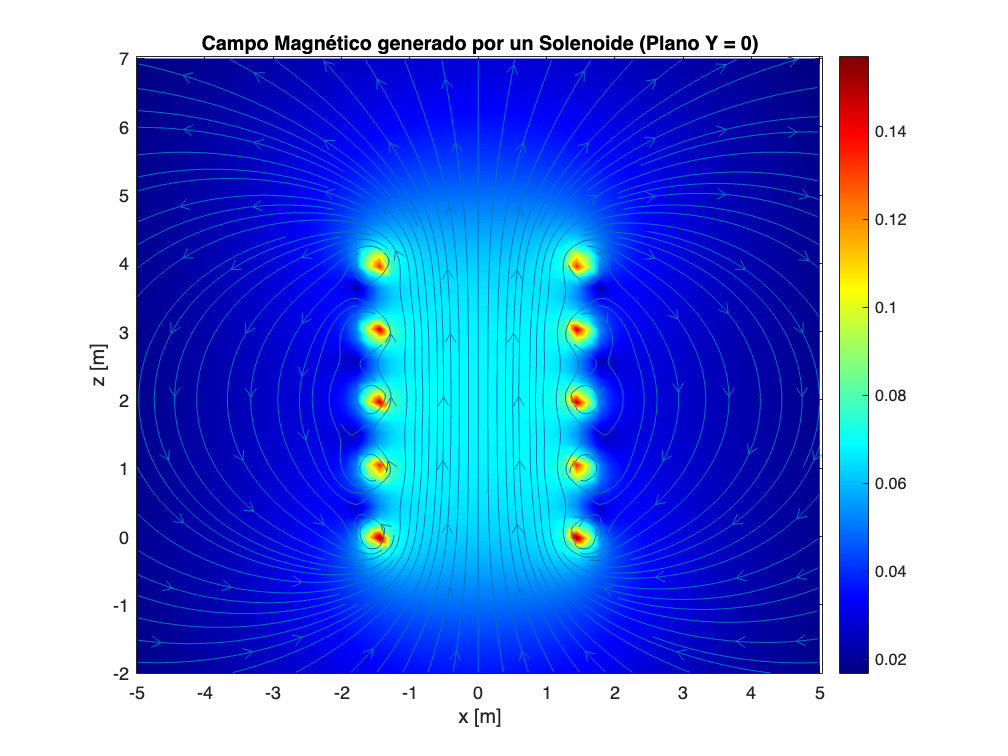

nl = 5;                % Número de vueltas
N = 20;                % Puntos por vuelta
R = 1.5;               % Radio del solenoide
sz = 1;                % Separación entre vueltas
I = 300;               % Corriente
mo = 4*pi*1e-7;        % Permeabilidad del vacío
km = mo * I / (4*pi);  % Constante

lx = 60; Ly = 1; Lz = 60; % cantidad de puntos en los ejes
x = linspace(-5, 5, lx);
y = 0;
z = linspace(-2, nl*sz + 2, Lz);
[X, Z] = meshgrid(x, z);

% se inicializan las matrices
Bx = zeros(Lz, lx);
Bz = zeros(Lz, lx);

for i = 1:lx
    for j = 1:Ly
        for k = 1:Lz
            B = [0, 0, 0];  

            for l = 1:nl*N
                vuelta = fix((l - 1) / N); % vuelta del selenoide    
                punto = l - vuelta*N;  % el punto dentro de la vuelta           
                theta = 2*pi*(punto - 1)/N;        
                rc = [R*cos(theta), R*sin(theta), vuelta*sz]; % posición en coordenadas

                dtheta = 2*pi/N;
                dl = [-R*sin(theta)*dtheta, R*cos(theta)*dtheta, 0]; % vector diferencial

                rp = [x(i), y, z(k)];

                r = rp - rc;
                r_norm = norm(r);

                if r_norm ~= 0
                    dB = km * cross(dl, r) / (r_norm^3); % ley de biot-savart
                    B = B + dB;
                end
            end

            Bx(k, i) = B(1);
            Bz(k, i) = B(3);
        end
    end
end


Bmag = sqrt(Bx.^2 + Bz.^2); % magnitud del campo magnetico

figure;
pcolor(x, z, Bmag.^(1/3)); shading interp;
colormap(jet); colorbar;
hold on;
streamslice(x, z, Bx, Bz, 2);  

xlabel('x [m]');
ylabel('z [m]');
title('Campo Magnético generado por un Solenoide (Plano Y = 0)');
axis equal tight;

Este código simula el campo magnético de un solenoide finito. El campo magnético generado por un conductor con corriente se calcula usando la Ley de Biot-Savart, que involucra una integral sobre la trayectoria de la corriente. Aquí, esa integral se aproxima mediante sumas discretas. El solenoide modelado es una serie de espiras circulares alineadas a lo largo del eje z, con corriente constante. En su interior, el campo magnético es intenso y aproximadamente uniforme, mientras que en el exterior, el campo disminuye rápidamente. 